# Code to call your function

%
%  Here are two examples of how to call the function using two different input signals
%
%  There are two inputs to the function.  These could be an input time
%  sequence and an impulse response of the system, but in reality can be
%  any two discrete sequences.
%
%  The call to the function is
%
%  [yOut, Debug] = Convolution( aIn, bIn )
%
%  The input arguments in this example are:
%
%  xIn -- A vector of any length that may represent a discrete input signal.
%  bIn -- A vector of any length that may represent the impulse
%              response to a system
%
%  The output arguments are:
%
%  yOut -- A vector of length M+N-1 where M and N are in the lengths of the
%          two input arguments.  yOut is the discrete convolution of the
%          two sequences
%
%  Debug -- This is an optional output argument that is a structure.  This
%           can be used to pass variables from within the function to the 
%           calling routine.  Variables internal to a function variables normally
%           can't be accessed outside of the function but this is a way to
%           sneak a variable back to the calling function.  Withing the
%           function assign a value using the 'dot' notation.  That is
%           Debug.variableName = variableName;
%
%           Thne in the calling routine you can print, plot, whatever the
%           variable by accessing Debug.variableName.
%

## Example 1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x = [1,2,3,4,5,6,7,8,9,10];
h = [1];

[y, Debug] = Convolution(x, h);

%  Check the sequence lengths
M = length(h);
N = length(x);
correctOutputLength = M + N - 1;

yLength = length(y);

if yLength == correctOutputLength
    fprintf('The output sequence has the correct length M+N-1!');
else
    fprintf('The output sequence has the incorrect length.  Check your code');
end

The output sequence has the correct length M+N-1!



%  Display the two sequences.  They should be the same.

disp(x)

     1     2     3     4     5     6     7     8     9    10



disp(y)

     1     2     3     4     5     6     7     8     9    10



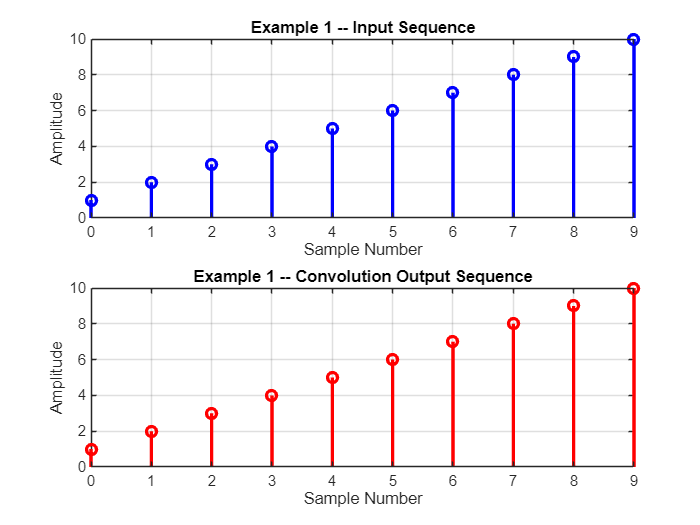


%  Plot the input and the output sequences

figure
subplot(2,1,1)
stem([0:N-1],x,'LineWidth',2,'Color','b')
grid on
title('Example 1 -- Input Sequence');
xlabel('Sample Number');
ylabel('Amplitude');

subplot(2,1,2)
stem([0:yLength-1],y,'LineWidth',2,'Color','r')
grid on
title('Example 1 -- Convolution Output Sequence');
xlabel('Sample Number');
ylabel('Amplitude');


%  End of Example 1
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Example 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%  Low pass filter impulse response

h = [  0.0275,    0.0877,   -0.0837,   -0.0667,    0.3061,...
    0.5746,    0.3061,   -0.0667,   -0.0837,    0.0877,    0.0275];

% Two tone input signal
x = sin(2*pi*.13 * [0:99]) + cos(2*pi*.4 * [0:99]);

%  Apply the filter to the input two-tone sequence by convolving the input
%  x with the filter impulse response h

[y, debug] = Convolution(x, h);

Index exceeds the number of array elements. Index must not exceed 100.

Error in Convolution (line 64)
                yOut(i) = yOut(i) + impulseH(j) * inputX(i-j + 1);  % multiply input by impulse response and sum each multiple moving from right to left


% Plot the input and the output

figure
subplot(2,1,1)
plot(x, 'LineWidth',2);
grid on
title('Multi-tone Input of the Convolution')
xlabel('Sample Number')
ylabel('Amplitude')

%  Plot the output of the convolution 

subplot(2,1,2)
plot(y, 'LineWidth',2,'Color','r')
grid on
title('Output of the Convolution')
xlabel('Sample Number')
ylabel('Amplitude')

%  End of Example 2
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Test 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%

aIn = 1;
bIn = ones(1,5); 

M = length(aIn);
N = length(bIn);

yOut = Convolution( aIn, bIn);

yLength = length( yOut );
fprintf('First Trial\n')
fprintf('The length of aIn is M = %d.\n  The length of bIn is N = %d.\n  The length of output sequence y should be M+N-1 = %d.\n  The actual length of y is %d\n\n', M, N, M+N-1, yLength );


aIn = ones(1,5);
bIn = 1; 

M = length(aIn);
N = length(bIn);

yOut = Convolution( aIn, bIn);

yLength = length( yOut );

fprintf('Second Trial\n')
fprintf('The length of aIn is M = %d\n.  The length of bIn is N = %d\n.  The length of output sequence y should be M+N-1 = %d\n.  The actual length of y is %d', M, N, M+N-1, yLength );

%  End of Test 2
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Test 3 %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x = [1,2,3,4,5,6,7,8,9,10];
h = [1];

N = length(x);

[y, Debug] = Convolution(x, h);
yLength = length(y);

%  Plot the input and the output sequences

figure
subplot(2,1,1)
stem([0:N-1],x,'LineWidth',2,'Color','b')
grid on
title('Example 1 -- Input Sequence');
xlabel('Sample Number');
ylabel('Amplitude');

subplot(2,1,2)
stem([0:yLength-1],y,'LineWidth',2,'Color','r')
grid on
title('Example 1 -- Convolution Output Sequence');
xlabel('Sample Number');
ylabel('Amplitude');

%  End of Test 3
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Test 4 %%%%%%%%%%%%%%%%%%%%%%%%%%%%

%  Create a sequence with lengths 9 and 3 respectively.  The number of end
%  effects will be 3-1 = 2

x = [1, 3, -6, 8,-3, 4, 7,-2, 5];
h = [1,-1, 2];

M = length(x);
N = length(h);

y = Convolution( x, h ); 

yLength = length(y);

%
%  For this example the end-effects at the beginning of the sequence will
%  be 1*1 = 1 and (3*1) + (-1*1) = 2 or [1,2]
%
%  The end-effects at the end of the sequence will be 
%  (2*-2) + (5*-1) = -9 and (5*2) = 10 or [-9, 10]
%

fprintf('The first two values of the end effects are %d and %d\n', y(1), y(2) );
fprintf('The last two values of the end effects are %d and %d', y(end-1), y(end) );

%  End of Test 4
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Test 5 %%%%%%%%%%%%%%%%%%%%%%%%%%%%

%  Low pass filter impulse response

h = [  0.0275,    0.0877,   -0.0837,   -0.0667,    0.3061,...
    0.5746,    0.3061,   -0.0667,   -0.0837,    0.0877,    0.0275];

% Two tone input signal
x = sin(2*pi*.09 * [0:99]) + .75*cos(2*pi*.37 * [0:99]);

%  Apply the filter to the input two-tone sequence by convolving the input
%  x with the filter impulse response h

[y, debug] = Convolution(x, h);

% Plot the input and the output
% Plot the input and the output

figure
subplot(2,1,1)
plot(x, 'LineWidth',2);
grid on
title('Multi-tone Input of the Convolution')
xlabel('Sample Number')
ylabel('Amplitude')

%  Plot the output of the convolution 

subplot(2,1,2)
plot(y, 'LineWidth',2,'Color','r')
grid on
title('Output of the Convolution')
xlabel('Sample Number')
ylabel('Amplitude')

%  End of Test 5
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Test 6 %%%%%%%%%%%%%%%%%%%%%%%%%%%%

%  The two input sequences

x = [  1, 4, 5, 2, -3, 8, -1, 3, 4, 1 ];
h = [ 1, -3, -2, 4, 2, 3,-1 ];


[y, debug] = Convolution(x, h);

fprintf('The output of the convolution is:\n')
fprintf('%d,', y);

% Plot the input and the output
% Plot the input and the output

figure
stem(y, 'LineWidth',2);
grid on
title('Homework Problem 6 -- Solution')
xlabel('Sample Number')
ylabel('Amplitude')


%  End of Test 6
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%